**Writing Data to a File**

format short
myMatrix = rand(3, 3)

myMatrix =     0.8143    0.3500    0.6160
    0.2435    0.1966    0.4733
    0.9293    0.2511    0.3517


% NOTE: save will always overwrite the file if
% it exists. 
save testMatrixFile.dat myMatrix -ascii
type testMatrixFile.dat


   8.1428483e-01   3.4998377e-01   6.1604468e-01
   2.4352497e-01   1.9659525e-01   4.7328885e-01
   9.2926362e-01   2.5108386e-01   3.5165951e-01



save testMatrixFileTxt.txt myMatrix -ascii
type testMatrixFileTxt.txt


   8.1428483e-01   3.4998377e-01   6.1604468e-01
   2.4352497e-01   1.9659525e-01   4.7328885e-01
   9.2926362e-01   2.5108386e-01   3.5165951e-01


**Appending Data to a File**

mat = randi([10,78], 3,3)

mat =     67    73    62
    50    29    36
    47    62    49


save testMatrixFile.dat mat -ascii -append
type testMatrixFile.dat


   8.1428483e-01   3.4998377e-01   6.1604468e-01
   2.4352497e-01   1.9659525e-01   4.7328885e-01
   9.2926362e-01   2.5108386e-01   3.5165951e-01
   6.7000000e+01   7.3000000e+01   6.2000000e+01
   5.0000000e+01   2.9000000e+01   3.6000000e+01
   4.7000000e+01   6.2000000e+01   4.9000000e+01



save testMatrixFileTxt.txt mat -ascii -append
type testMatrixFileTxt.txt


   8.1428483e-01   3.4998377e-01   6.1604468e-01
   2.4352497e-01   1.9659525e-01   4.7328885e-01
   9.2926362e-01   2.5108386e-01   3.5165951e-01
   6.7000000e+01   7.3000000e+01   6.2000000e+01
   5.0000000e+01   2.9000000e+01   3.6000000e+01
   4.7000000e+01   6.2000000e+01   4.9000000e+01


**Reading from a File**

% Matlab always loads the result in a matrix
% variable with same name as the file. 
clear % all variables
load testMatrixFile.dat
load testMatrixFileTxt.txt
who


Your variables are:

testMatrixFile     testMatrixFileTxt  



testMatrixFile

testMatrixFile =     0.8143    0.3500    0.6160
    0.2435    0.1966    0.4733
    0.9293    0.2511    0.3517
   67.0000   73.0000   62.0000
   50.0000   29.0000   36.0000
   47.0000   62.0000   49.0000


testMatrixFileTxt

testMatrixFileTxt =     0.8143    0.3500    0.6160
    0.2435    0.1966    0.4733
    0.9293    0.2511    0.3517
   67.0000   73.0000   62.0000
   50.0000   29.0000   36.0000
   47.0000   62.0000   49.0000


NOTE: Save only writes from a matrix to a file and load only passes on the values in file to a matrix. Lower level functions in Chp9. 

**Load from File and Plot the Datta**

% making the data file
xs = 0:3:21;
ys = [55.5 52.4 52.6 55.7 75.6 77.7 70.3 66.6];
mat = [xs; ys]

mat =          0    3.0000    6.0000    9.0000   12.0000   15.0000   18.0000   21.0000
   55.5000   52.4000   52.6000   55.7000   75.6000   77.7000   70.3000   66.6000



save TimeTempData.dat mat -ascii

clear
% loading data from file and plotting it
load TimeTempData.dat
who


Your variables are:

TimeTempData  




xsTime = TimeTempData(1,:)

xsTime =      0     3     6     9    12    15    18    21


ysTemp = TimeTempData(2, :)

ysTemp =    55.5000   52.4000   52.6000   55.7000   75.6000   77.7000   70.3000   66.6000


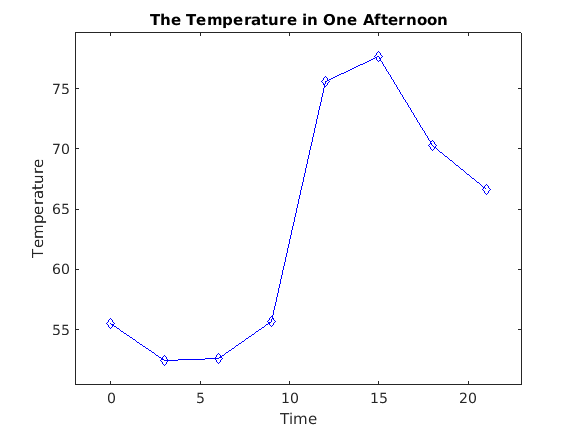


xMin = min(xsTime);
xMax = max(xsTime);
yMin = min(ysTemp);
yMax = max(ysTemp);

% Plot
axis([xMin-2, xMax+2, yMin-2, yMax+2])

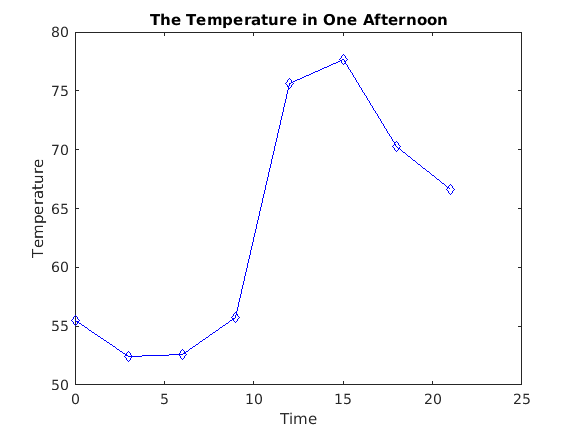

plot(xsTime, ysTemp, 'bd-')
xlabel('Time')
ylabel('Temperature')
title('The Temperature in One Afternoon')